# Examen Final

#### Eleazar Olivas Gaspar A01731405

Robot Planar 2 GDL

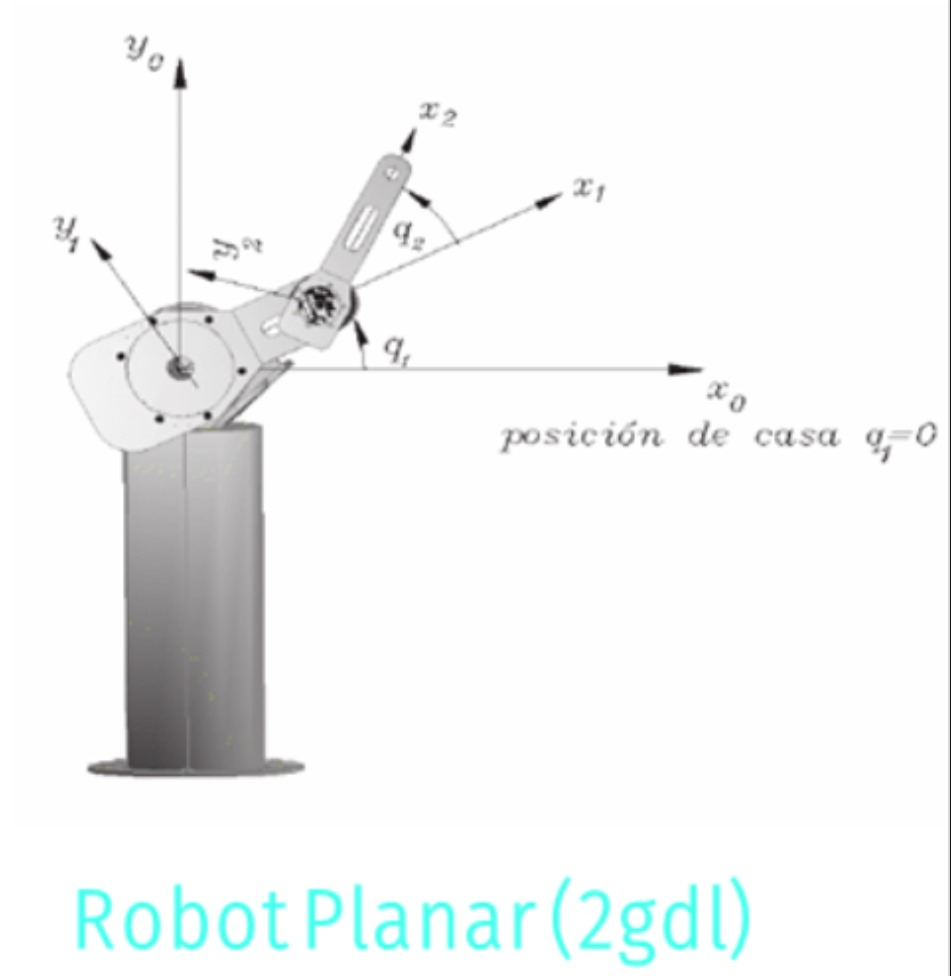

    Se limpia el entorno de trabajo, consola, workspace, cierra ventanas.

%Limpieza de pantalla
clear all
close all
clc

%Temporizador
tic

    Se hace la declaración de variables simbolicas.

se guarda al variable para la pocisión angulo ambas articulaciones llamadas th1 y th2, al mismo tiempo que t, para representar el tiempo en el que cambian dichos angulos. Por otro lado se guardan las velocidades con las que cambia este angulo en las variables, the1p y th2p; esta nomenclatura biene del punto que representa la derivada de la posición. Para finalizar con los angulos se añade el th1pp y th2pp los cuales son las aceleraciones del movimiento de las juntas. 

Después de inicializar las variables para el mdoeloado de los ángulos, se definen las masas en m1 y m1; almismo tiempo que la posición con las cordenadas Ixx1, yy1, Izz1, Ixx2, yy2, Izz2. Después de esto se añaden las longitudes del brazo y la distancia del centro de masa del estabón. 

Se finaliza la declaración de variables simbolicas con la definición de pi, la gravedad, aceleración, 0 para el calculos de coriolis.

%Declaración de variables simbólicas

%Angulos de cada articulación
syms th1(t) th2(t) t  
%Velocidades de cada articulación
syms th1p(t) th2p(t)  
%Aceleraciones de cada articulación
syms th1pp(t) th2pp(t) 
%Masas y matrices de Inercia
syms m1 m2  Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 
%l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms l1 l2 lc1 lc2  
%pi, gravedad, aceleración, 0
syms pi g a cero

    Se define el vector de coordenadas articulares.

Se define en Q el vactor de coordenadas articulares, en Qp las velocidades y en Qpp las aceleraciones.

 %Creamos el vector de coordenadas articulares
  Q= [th1; th2];
 disp('Coordenadas articulares');

Coordenadas articulares


 pretty (Q);

/ th1(t) \
|        |
\ th2(t) /



 
 %Creamos el vector de velocidades articulares
  Qp= [th1p; th2p];
 disp('Velocidades articulares');

Velocidades articulares


 pretty (Qp);

/ th1p(t) \
|         |
\ th2p(t) /




 %Creamos el vector de aceleraciones articulares
  Qpp= [th1pp; th2pp];
 disp('Aceleraciones articulares');

Aceleraciones articulares


 pretty (Qpp);

/ th1pp(t) \
|          |
\ th2pp(t) /



    Configuracion del robot.

Se configura el tipo de junta en [0 0] debido a que es un robot planar con 2 juntas rotacionales.

Posteriormente se guardan los grados de libertad y se pasan a un string. 

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

    Configuración de la primera articulación.

Para la primera articulacion se hace el desplazamiento de z par mover el robot del su origen a donde empieza la junta 1, y se hace el modelado de el movimiento en x y y par ael movimiento de la misma, en cuanto a la matriz rotacional se hace la multiplicación de la rotacion sobre z con la rotación que se hace para alinear el eje.

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1);0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];


    Segunda articulación.

Para la segunda junta se vuelve a modelar el movimiento de la junta respecto a x y y ademas de la rotacion que se hace sobre el eje z.

%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];

    Se hacen las matrices homogeneas

Se inicia un vector [0 0 0] par hace la  atriz homogenea con la siguiente organización.

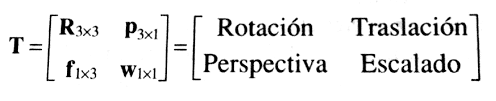

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
%     disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
%     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

    Se saca el jacobiano de forma diferencial y analítica.

El jacobiano es importante pues es la herramienta que usamos para el calculo diferencial de vectores. con el fin de obtener las velocidades lineales y angulares del modelo.

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            %Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];
            %Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
% pretty(Jacobiano);

Una vez teniendo el jacobiano podemos pasar a obtener los vectores de velocidades lineales y angulares segun sea el caso; estas se guardan en v  y w respectivamente.

%Obtenemos vectores de Velocidades Lineales y Angulares
% disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Qp)

$$V(t) = \begin{array}{l} \left(\begin{array}{c} -\mathrm{th1p}\left(t\right)\,\left(l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sigma_{1}\right)-l_{2}\,\sigma_{1}\,\mathrm{th2p}\left(t\right)\\ \mathrm{th1p}\left(t\right)\,\left(l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sigma_{2}\right)+l_{2}\,\sigma_{2}\,\mathrm{th2p}\left(t\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left({\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right)\right) \end{array}$$

% pretty(V);
% disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Qp) 

$$W(t) = \left(\begin{array}{c} 0\\ 0\\ \mathrm{th1p}\left(t\right)+\mathrm{th2p}\left(t\right) \end{array}\right)$$

%     pretty(W);

    Energia cinética del robot.

Se hace el calculo para entender la energía que se lleva el movimiento del robot de 2 GDL.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética
%%%%%%%%%%%%%%%%%%%%%%%%%%Omitimos la división de cada lc%%%%%%%%%%%%%%%
%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, lc1);
 P02=subs(P(:,:,2), l2, lc2);

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

%Ayuda a calcular la fuerza y su reflejo en la aceleracion.




I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

%Función de energía cinética

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%Calculamos las velocidades para cada eslabón 

%Eslabón 1

%Calculamos el jacobiano lineal de forma analítica
Jv_a1(:,GDL-1)=PO(:,:,GDL-1);
Jw_a1(:,GDL-1)=PO(:,:,GDL-1);


Debido a que ya se saco el jacobiano del efector final para completar el calculo de la inercia se hace el calculo del brazo anterior, es por esto que en el calcúlon de k-1

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
 %disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');
Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
 %pretty(V1);
 % disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');
W1=simplify (Jw_a1*Qp(1));
 % pretty(W1);


%Eslabón 2
%Ya lo calculamos previamente al multiplicar la matriz jacobiana por Qp

%%%%%%%%%%%%%%%%%%%%%%%%
%Calculamos la energía cinética para cada eslabon

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

              2            2     ______           __                     2           2
Izz1 |th1p(t)|    |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
--------------- + ---------------------------------------------------------------------
       2                                         2 l1 lc1





%Eslabón 2
V2_Total= V+cross(W,P02);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W)'*(I2*W);
disp('Energía Cinética en el Eslabón 3');

Energía Cinética en el Eslabón 3


K2= simplify (K2)

$$K2 = \begin{array}{l} \frac{\bar{m_{2}}\,\left(\mathrm{th1p}\left(t\right)\,\left(l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\sin\left(\sigma_{4}\right)\right)+l_{2}\,\sin\left(\sigma_{4}\right)\,\mathrm{th2p}\left(t\right)+{\mathrm{lc}}_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sigma_{1}\right)\,\left(\bar{\mathrm{th1p}\left(t\right)}\,\left(\sin\left(\sigma_{3}\right)\,\bar{l_{2}}+\sin\left(\bar{{\mathrm{th}}_{1}\left(t\right)}\right)\,\bar{l_{1}}\right)+\bar{\mathrm{th2p}\left(t\right)}\,\sin\left(\sigma_{3}\right)\,\bar{l_{2}}+\sin\left(\bar{{\mathrm{th}}_{2}\left(t\right)}\right)\,\bar{{\mathrm{lc}}_{2}}\,\sigma_{2}\right)}{2}+{\mathrm{Izz}}_{2}\,\sigma_{1}\,\left(\frac{\bar{\mathrm{th1p}\left(t\right)}}{2}+\frac{\bar{\mathrm{th2p}\left(t\right)}}{2}\right)+\frac{\bar{m_{2}}\,\left(\mathrm{th1p}\left(t\right)\,\left(l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)+l_{2}\,\cos\left(\sigma_{4}\right)\right)+l_{2}\,\cos\left(\sigma_{4}\right)\,\mathrm{th2p}\left(t\right)+{\mathrm{lc}}_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sigma_{1}\right)\,\left(\bar{\mathrm{th1p}\left(t\right)}\,\left(\cos\left(\sigma_{3}\right)\,\bar{l_{2}}+\cos\left(\bar{{\mathrm{th}}_{1}\left(t\right)}\right)\,\bar{l_{1}}\right)+\bar{\mathrm{th2p}\left(t\right)}\,\cos\left(\sigma_{3}\right)\,\bar{l_{2}}+\cos\left(\bar{{\mathrm{th}}_{2}\left(t\right)}\right)\,\bar{{\mathrm{lc}}_{2}}\,\sigma_{2}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{th1p}\left(t\right)+\mathrm{th2p}\left(t\right)\\ \sigma_{2}=\bar{\mathrm{th1p}\left(t\right)}+\bar{\mathrm{th2p}\left(t\right)}\\ \sigma_{3}=\bar{{\mathrm{th}}_{1}\left(t\right)}+\bar{{\mathrm{th}}_{2}\left(t\right)}\\ \sigma_{4}={\mathrm{th}}_{1}\left(t\right)+{\mathrm{th}}_{2}\left(t\right) \end{array}$$

%pretty (K2);

K_Total= simplify (K1+K2)

%pretty (K_Total)

    Como siguiente paso caculamos la energia potencial

%Calculamos la energía potencial para cada uno de los eslabones

%Obtenemos las alturas respecto a la gravedad
 h1= P01(2); %Tomo la altura paralela al eje y
 h2= P02(2); %Tomo la altura paralela al eje y

 %Calculamos la energía potencial total
 U1=m1*g*h1;
 U2=m2*g*h2;
 U_Total= U1 + U2;

Larangiano y modelo de energía.

 %Obtenemos el Lagrangiano
 Lagrangiano= simplify (K_Total-U_Total);
 %pretty (Lagrangiano);

%Modelo de Energía
 H= simplify (K_Total+U_Total);
  %pretty (H)

Para las ecuaciones de movimento, usamos el Lagrangiano derivado con respecto a la primera coordenada generalizada de velocidad, se usa un vector columna de derivadas con respecto al tiempo para las velocidades y aceleracions ya derivadas.

    Torque 

  %%%%%%%%%%%%%%%%%%%%%%Ecuaciones de Movimiento%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 Qd=[th1p(t); th2p(t); th1pp(t); th2pp(t)];

 %Obtenemos las derivadas de la velocidad en la primera coordenada
 %generalizada
 dQ1=[diff(diff(Lagrangiano,th1p), th1),diff(diff(Lagrangiano,th1p), th2),... %Derivamos con respecto a la primera velocidad generalizada th1p para las 2 posiciones articulaciones
     diff(diff(Lagrangiano,th1p), th1p),diff(diff(Lagrangiano,th1p), th2p)];%Derivamos con respecto a la primera velocidad generalizada th1p para las 2 velocidades articulaciones
 
 %Definimos el torque 1
 t1= dQ1*Qd- diff(Lagrangiano, th1);

Torque

 %Obtenemos las de derivadas de la velocidad en la segunda coordenada
 %generalizada

 dQ2=[diff(diff(Lagrangiano,th2p), th1),diff(diff(Lagrangiano,th2p), th2),... %Derivamos con respecto a la segunda velocidad generalizada th2p para las 3 posiciones articulaciones
     diff(diff(Lagrangiano,th2p), th1p),diff(diff(Lagrangiano,th2p), th2p)];%Derivamos con respecto a la segunda velocidad generalizada th2p para las 3 velocidades articulaciones

 %Definimos el torque 2
 t2= dQ2*Qd- diff(Lagrangiano, th2); 

    Fuerzas Centrípetas y de Coriolis

%Generación del Modelo Dinámico en forma matricial
%Matriz de Inercia
%Extraemos coeficientes de aceleraciones
M=[diff(t1, th1pp), diff(t1, th2pp);...
   diff(t2, th1pp), diff(t2, th2pp)];
rank (M);
M=M(t);

 %Fuerzas Centrípetas y de Coriolis
 %Definimos Mp
 M11=[diff(M(1,1),th1), diff(M(1,1),th2)]*Qp;%Se deriva parcialmente en el tiempo respecto a todas las variables 
 M12=[diff(M(1,2),th1), diff(M(1,2),th2)]*Qp;

 M21=[diff(M(2,1),th1), diff(M(2,1),th2)]*Qp;
 M22=[diff(M(2,2),th1), diff(M(2,2),th2)]*Qp;

  Mp=[M11, M12;...
     M21, M22];


%Definimos la energía cinética en su forma matricial
k=1/2*transpose(Qp)*M*Qp;

%Definimos dk

dk=[diff(k, th1); diff(k, th2)];

%Fuerzas centrípetas y de Coriolis
 C= Mp*Qp-dk;


 %Par Gravitacional
 %se sustituyen las velocidades y aceleraciones por 0
 r=cero;
 a1=subs(t1, th1p, r);
 a2=subs(a1, th2p, r);
 a3=subs(a2, th1pp,r);
 a4=subs(a3, th2pp,r);

 %Torque gravitacional en el motor 1
 G1=a4;

 
 b1=subs(t2, th1p, r);
 b2=subs(b1, th2p, r);
 b3=subs(b2, th1pp,r);
 b4=subs(b3, th2pp,r);

 %Torque gravitacional en el motor 2
 G2=b4;


% Vector de par gravitacional

disp("par gravitacional")

par gravitacional


G=[G1;G2]


 toc

Elapsed time is 6.830094 seconds.
